Load in the data

x = dir;
x(1:5) = [];
for i = 1:40
    Data{i} = fastqread(x(i).name);
end
Data=Data';
Total_reads = cellfun(@numel,Data);

Extract the insert:

reference Fwd: CGTCAAGTTGTCAGGTGGT, Rev: TCTGGTCGTAAAGGAGAA

for i = 1:40
    a = squeeze(struct2cell(Data{i}));
    a = a(2,:)';
    ind_fwd = strfind(a,'CGTCAAGTTGTCAGGTGGT'); ind_rev = strfind(a,'TCTGGTCGTAAAGGAGAA');
    ind = ~cellfun(@isempty,ind_fwd) &  ~cellfun(@isempty,ind_fwd);
    a = cellfun(@(x,y,z) x(y+19:z-1),a(ind),ind_fwd(ind),ind_rev(ind),'UniformOutput',false);
    [C,~,ic] = unique(a);
    a_counts = accumarray(ic,1);
    seq{i} = C(2:end);count{i} = a_counts(2:end);
end

Merge data from different samples

Seq_all = {};
for i = 1:20
    Seq_all = [Seq_all;seq{2*i-1};seq{2*i}];
end
Seq_all = unique(Seq_all);

smplsize = numel(Seq_all);
Freq_all = zeros(numel(Seq_all),20,2);
Count_all = zeros(numel(Seq_all),20,2);
for i = 1:20
    [~,index] = ismember(seq{2*i-1},Seq_all);
    match_ind = find(index);
    Freq_all(index(match_ind),i,1) = count{2*i-1}(match_ind)/Total_reads(2*i-1);
    Count_all(index(match_ind),i,1) = count{2*i-1}(match_ind);
    [~,index] = ismember(seq{2*i},Seq_all);
    match_ind = find(index);
    Freq_all(index(match_ind),i,2) = count{2*i}(match_ind)/Total_reads(2*i);
    Count_all(index(match_ind),i,2) = count{2*i}(match_ind);
end
Seq_raw = Seq_all;Freq_raw = Freq_all;Count_raw = Count_all;

Seq_all = Seq_raw;Freq_all = Freq_raw;Count_all = Count_raw;

Core = 'CTGCCGTATAGGCAG';
start_ind = cellfun(@(x) strfind(x,Core),Seq_all,'UniformOutput',false);
ind = cellfun(@isempty,start_ind);
Seq_all(ind) = [];
Freq_all(ind,:,:) =[];
Count_all(ind,:,:) =[];

ind_SL6 = cellfun(@(x) find(contains(SeqSL6,x)),Seq_all,'UniformOutput',false);

total_count = squeeze(sum(sum(Freq_all,3),2));

ind = find(total_count==0);
Seq_all(ind) = [];
Freq_all(ind,:,:) =[];
Count_all(ind,:,:) =[];
merge_count = squeeze(mean(Count_all,3));

ind = find(sum(merge_count(:,1:10),2)<5 & sum(merge_count(:,11:20),2)<5);
Seq_all(ind) = [];
Freq_all(ind,:,:) =[];
Count_all(ind,:,:) =[];
merge_freq = squeeze(mean(Freq_all,3));

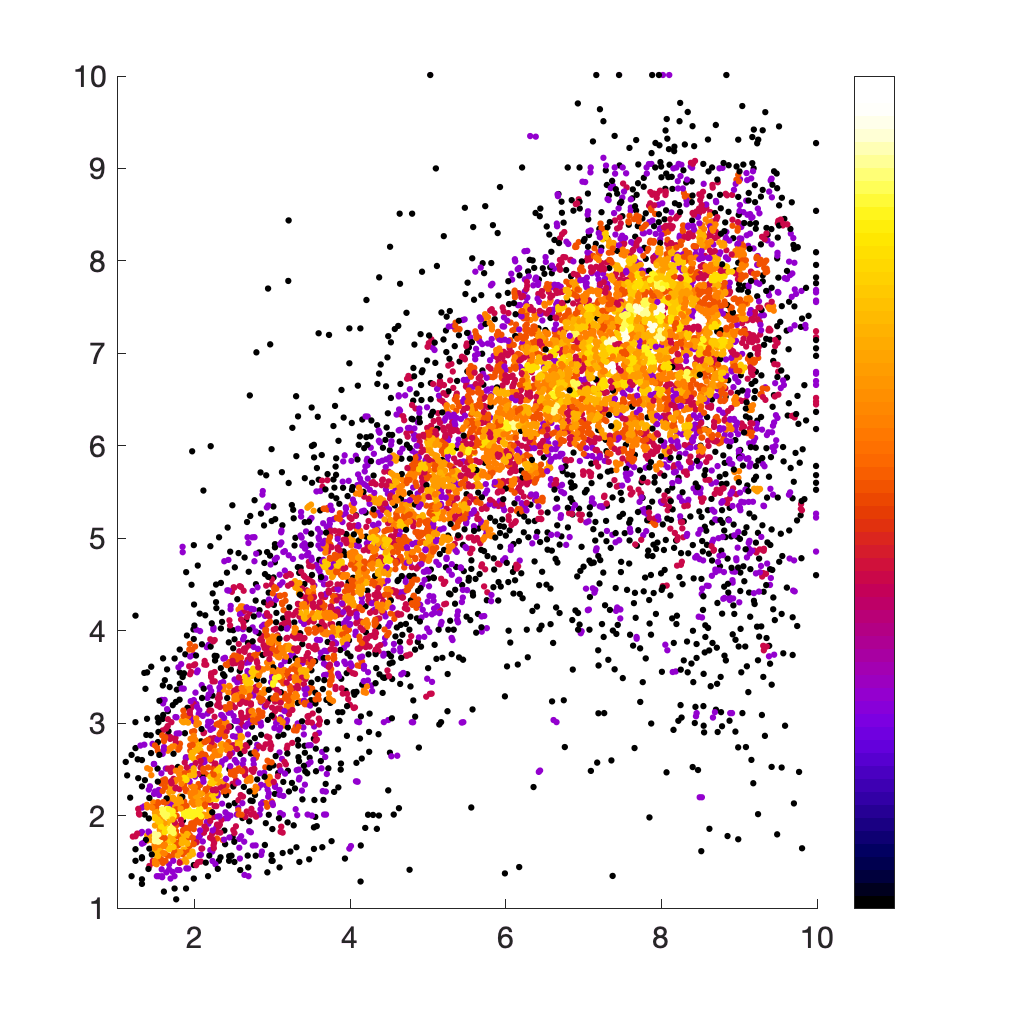

Mu_ctrl = sum((ones(numel(Seq_all),1)*(1:10)).*merge_freq(:,1:10),2)./sum(merge_freq(:,1:10),2);
Mu_exp = sum((ones(numel(Seq_all),1)*(1:10)).*merge_freq(:,11:20),2)./sum(merge_freq(:,11:20),2);

ind = find(~isnan(Mu_ctrl) & ~isnan(Mu_exp));
x = Mu_ctrl(ind);y = Mu_exp(ind);
ind = find(x>1 & y > 1);
x = x(ind);y = y(ind);

[value,c] = hist3([x,y],'Nbins',[99 100]);
labels = size(x);
for i = 1:numel(x)
    [~,j] = min(abs(x(i)-c{1}));
    [~,k] = min(abs(y(i)-c{2}));
    labels(i) = log10(value(j,k));
end

figure('Renderer', 'painters', 'Position', [10 10 510 510])
scatter(x,y,10,labels,'filled')
colormap(fire)
colorbar('Ticks',[])
set(gca,'FontSize',15)
axis([1 10 1 10])

Seq_filter = Seq_all(ind);
merge_freq = merge_freq(ind,:);
[~,P] = ttest2(merge_freq(:,1:10)',merge_freq(:,11:20)');
[FDR,Q] = mafdr(P);
index_Q = find(Q<0.01);% cutoff threshold at 0.01

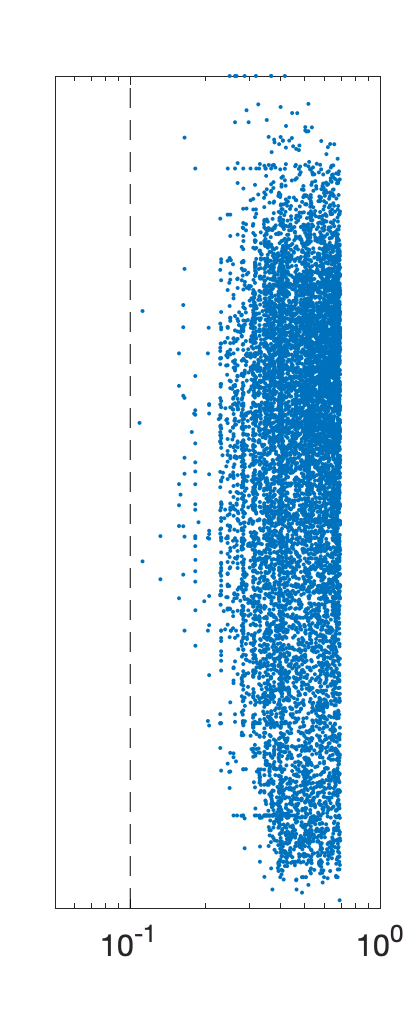

figure('Renderer', 'painters', 'Position', [10 10 210 510])
[~,i] = sort(y);
plot(Q(i),y(i),'.')
hold on
plot([0.1 0.1],[1 10],'k--')
xlim([0.05 1])
set(gca,'xscale','log')
set(gca,'FontSize',15);
yticks([]);